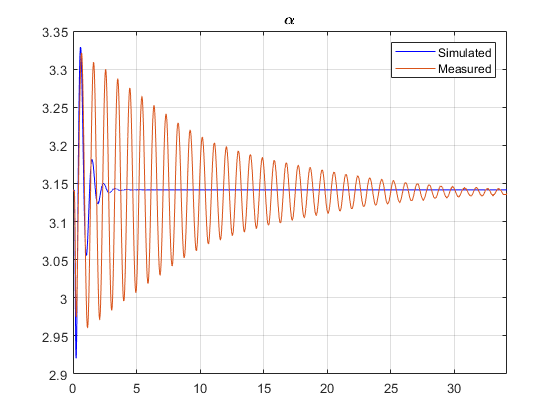

clc
clear
close all

Validation_Start_Up

v = 0.20; % Maximum variation of parameter = +-20%
step = 0.01; % Step variation = 1%
esp = 38; % Esperimento da validare (al momento va solo questo)
% B_p
def1 = nB_p;
max1 = def1*(1 + v);
min1 = def1*(1 - v);
s1 = def1*step;
B_p = 0.0024;

% B_r
def2 = nB_r;
max2 = def2*(1 + v);
min2 = def2*(1 - v);
s2 = def2*step;
B_r = 0.0024;

% eta_g
def3 = neta_g;
max3 = def3*(1 + v);
min3 = def3*(1 - v);
s3 = def3*step;
eta_g = 0.9;

% eta_m
def4 = neta_m;
max4 = def4*(1 + v);
min4 = def4*(1 - v);
s4 = def4*step;
eta_m = 0.69;

% g
def5 = ng;
max5 = def5*(1 + v);
min5 = def5*(1 - v);
s5 = def5*step;
g = 9.81;

% J_a
def6 = nJ_a;
max6 = def6*(1 + v);
min6 = def6*(1 - v);
s6 = def6*step;
J_a = 0.002;

% J_p
def7 = nJ_p;
max7 = def7*(1 + v);
min7 = def7*(1 - v);
s7 = def7*step;
J_p = 0.0012;

% K_g
def8 = nK_g;
max8 = def8*(1 + v);
min8 = def8*(1 - v);
s8 = def8*step;
K_g = 70;

% k_m
def9 = nk_m;
max9 = def9*(1 + v);
min9 = def9*(1 - v);
s9 = def9*step;
k_m = 0.00768;

% k_t
def10 = nk_t;
max10 = def10*(1 + v);
min10 = def10*(1 - v);
s10 = def10*step;
k_t = 0.00768;

% l_p
def11 = nl_p;
max11 = def11*(1 + v);
min11 = def11*(1 - v);
s11 = def11*step;
l_p = 0.156;

% m_p
def12 = nm_p;
max12 = def12*(1 + v);
min12 = def12*(1 - v);
s12 = def12*step;
m_p = 0.127;

% r
def13 = nr;
max13 = def13*(1 + v);
min13 = def13*(1 - v);
  s13 = def13*step;
r = 0.216;

% R_m
def14 = nR_m;
max14 = def14*(1 + v);
min14 = def14*(1 - v);
  s14 = def14*step;
R_m = 2.678;

nJ_T = (J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p);
% J_T
def15 = nJ_T;
max15 = def15*(1 + v);
min15 = def15*(1 - v);
  s15 = def15*step;
J_T = 0.0000156917184;


[A,B,C,D] = SS_Matrices_Voltage_Stable(B_p,B_r,J_T,J_a,J_p,K_g,R_m,eta_g,eta_m,g,k_m,k_t,l_p,m_p,r);
C = eye(4);
D = zeros(4,1);
% State-space model
system = ss(A,B,C,D);

cd ./esp
cd ./alpha_d_esp
alpha_d_esp_struct = load("alpha_d_esp"+esp);
alpha_d_esp = cell2mat(struct2cell(alpha_d_esp_struct));
cd ..

cd ./alpha_esp
alpha_esp_struct = load("alpha_esp"+esp);
alpha_esp = cell2mat(struct2cell(alpha_esp_struct));
cd ..

cd ./t_esp
t_esp_struct = load("t_esp"+esp);
t_esp = cell2mat(struct2cell(t_esp_struct));
cd ..

cd ./theta_d_esp
theta_d_esp_struct = load("theta_d_esp"+esp);
theta_d_esp = cell2mat(struct2cell(theta_d_esp_struct));
cd ..

cd ./theta_esp
theta_esp_struct = load("theta_esp"+esp);
theta_esp = cell2mat(struct2cell(theta_esp_struct));
cd ..

cd ./voltage_esp
voltage_esp_struct = load("voltage_esp"+esp);
voltage_esp = cell2mat(struct2cell(voltage_esp_struct));
cd ..
cd ..

alpha_sim = lsim(system(2),voltage_esp,t_esp); % simulata

plot(t_esp,alpha_sim+pi,"blue")
hold on
plot(t_esp,alpha_esp)
hold off
xlim([0 t_esp(length(t_esp))])
title('\alpha')
grid on
legend ('Simulated','Measured')

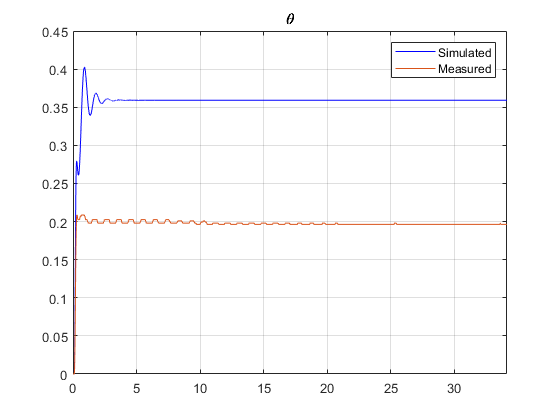


theta_sim = lsim(system(1),voltage_esp,t_esp); % simulata

plot(t_esp,theta_sim,"blue")
hold on
plot(t_esp,theta_esp)
hold off
xlim([0 t_esp(length(t_esp))])
title('\theta')
grid on
legend ('Simulated','Measured')